# Solutions to all tutorial exercises

Some tutorials have small exercises at the end. Solutions to these exercises are collected here, in alphabetical order.

## Accessing physiology and drug databases

adult = Physiology('human35m'); % or human35f
child = Physiology('human5u');  % or other ages
rat   = Physiology('rat475');
mouse = Physiology('mouse40');

tissues = {'adi' 'bon' 'bra' 'gut' 'hea' 'kid' 'liv' 'lun' 'mus' 'ski' 'spl'};

OWtis_adult = getvalue(adult, 'OWtis', tissues);
OWtot_adult = sum(OWtis_adult) + getvalue(adult, 'OWtbl');
ratio_adult = OWtot_adult / getvalue(adult, 'BW')

ratio_adult = 0.9337


OWtis_child = getvalue(child, 'OWtis', tissues);
OWtot_child = sum(OWtis_child) + getvalue(child, 'OWtbl');
ratio_child = OWtot_child / getvalue(child, 'BW')

ratio_child = 0.9224


OWtis_rat = getvalue(rat, 'OWtis', tissues);
OWtot_rat = sum(OWtis_rat) + getvalue(rat, 'OWtbl');
ratio_rat = OWtot_rat / getvalue(rat, 'BW')

ratio_rat = 0.9785


OWtis_mouse = getvalue(mouse, 'OWtis', tissues);
OWtot_mouse = sum(OWtis_mouse) + getvalue(mouse, 'OWtbl');
ratio_mouse = OWtot_mouse / getvalue(mouse, 'BW')

ratio_mouse = 0.9447

Result: least coverage in child (~92%), most in rat (~98%)

## Defining a dosing scheme

dosing_pneumonia = Infusion('Amoxicillin', 0*u.day:8*u.h:2*u.day+16*u.h, 2.2*u.g, 30*u.min, 'iv') ...
    + Oral('Clarithromycin', 0*u.day:12*u.h:2*u.day+12*u.h, 500*u.mg) ...
    + Oral('Amoxicillin', 3*u.day:8*u.h:6*u.day+16*u.h, 1000*u.mg)

dosing_pneumonia = 	ComplexDosing object with

Infusion dosing:

       Compound          Tstart          Tstop        Dose          Rate          Duration    Target
    _______________    ___________    ____________    _____    _______________    ________    ______

    {'Amoxicillin'}    0 day          0.020833 day    2.2 g    1.2222e-06 kg/s     30 min     {'iv'}
    {'Amoxicillin'}    0.33333 day    0.35417 day     2.2 g    1.2222e-06 kg/s     30 min     {'iv'}
    {'Amoxicillin'}    0.66667 day    0.6875 day      2.2 g    1.2222e-06 kg/s     30 min     {'iv'}
    {'Amoxicillin'}    1 day          1.0208 day      2.2 g    1.2222e-06 kg/s     30 min     {'iv'}
    {'Amoxicillin'}    1.3333 day     1.3542 

## Defining a physiology

rat1 = Covariates('Species','rat','BW',400*u.g,'sex','male','age',70*u.week)

rat1 = 	Physiology object:

	
species: rat
sex: male
age: 70 week
BW: 400 g



rat2 = Physiology('rat475')

rat2 = 	Physiology object:

	"rat475" with parameters

species: rat
type: F344
sex: male
age: 70 week
BW: 475 g
LBW: 399 g
fowtisBW: [11 values]
ftblBW: 0.064
hct: 0.43
pH: [13 values]
OWtis: [11 values]
OWtot: [11 values]
OWrbt: [11 values]
OWtbl: 30.4 g
fcelOWtot: [13 values]
fintOWtot: [13 values]
fvasOWtot: [13 values]
fresOWrbt: [11 values]
fcelOWtis: [13 values]
fintOWtis: [13 values]
faphOWtis: [12 values]
dens: [12 values]
Vtot: [11 values]
Vtis: [11 values]
Vvas: [11 values]
Vres: [11 values]
Vtbl: 3.04e-05 m^3
fcelVtot: [13 values]
fintVtot: [13 values]
fvasVtot: [13 values]
fcelVtis: [13 values]
fintVtis: [13 values]
fnliVtis: [13 values]
fnphVtis: [13 values]
faphVtis: [12 values]
fwecVtis: [11 values]
fwicVtis: [12 values]
fwtotVtis: [11 values]
fwecVrbt: [12 values]
fwicVrbt: [12 values]
fregVtbl: [11 values]
fartVtbl: 0.33333
fvenVtbl: 0.66667
rtpAlb: [11 values]
rtpLip: [11 values]
co: 0.13446 L/min
fqbloCO: [10 values]
Qblo: [1

rat3 = scaling_BW(rat2, rat1)

rat3 = 	Physiology object:

	"scaled from "rat475" with "scaling_BW"" with parameters

species: rat
age: 70 week
BW: 400 g
fowtisBW: [11 values]
ftblBW: 0.063931
hct: 0.43
pH: [13 values]
OWtis: [11 values]
OWtbl: 0.025572 kg
dens: [12 values]
Vtot: [11 values]
Vtis: [11 values]
Vvas: [11 values]
Vtbl: 2.5572e-05 m^3
fcelVtis: [13 values]
fintVtis: [13 values]
fnliVtis: [13 values]
fnphVtis: [13 values]
faphVtis: [12 values]
fwecVtis: [11 values]
fwicVtis: [12 values]
fwtotVtis: [11 values]
fregVtbl: [11 values]
fartVtbl: 0.33333
fvenVtbl: 0.66667
rtpAlb: [11 values]
rtpLip: [11 values]
co: 0.11311 L/min
fqbloCO: [10 values]
Qblo: [10 values]



## Importing experimental data

Dataset from the tutorial

data = ImportableData('data/Warfarin_Holford1986.csv','Delimiter',',');
data.maprow('Species','Covariate');
data.maprow('Warfarin oral dose','Oral dosing','Compound','Warfarin');
data.maprow('Warfarin plasma concentration','Record','Site','pla');
expid = import(data);

1 experimental dataset(s) imported successfully.


Dataset from the exercise

data2 = ImportableData('data/Warfarin_Holford1986_Variante.csv','Delimiter',',');
data2.maprow('Species','Covariate');
data2.maprow('Oral dose','Oral dosing');
data2.maprow('Concentration','Record');
data2.setattr('Site','SITE')

ans = 	ImportableData object:

File: Warfarin_Holford1986_Variante.csv

     TIME     NAME            VALUE            COMPOUND     SITE  
     (Time)   (Name)          (Value,Dose)     (Compound)   (Site)
     ------   -------------   --------------   ----------   ------
 1   0 h      Species         human                               
 2   0 h      Oral dose       15 mg            Warfarin           
 3   0.5 h    Concentration   472.4137 ug/L    Warfarin     pla   
 4   1 h      Concentration   1079.3103 ug/L   Warfarin     pla   
 5   2 h      Concentration   1351.7241 ug/L   Warfarin     pla   
 6   4 h      Concentration   1258.6206 ug/L   Warfarin     pla   
 7   8 h      Concentration   1110.3448 ug/L   Warfarin     pla   
 8   12 h     Concentration   979.3103 ug/L    Warfarin     pla   
 9   24 h     Concentration   713.7931 ug/L    Warfarin     pla   
10   32 h     Concentration   641.3793 ug/L    Warfarin     pla   

Mappings:


expid2 = import(data2)

1 experimental dataset(s) imported successfully.


expid2 = 	Individual object:

           type: 'Experimental data'
           name: 'ID 1'
         dosing: '1 Oral event(s)'
     physiology: '1 parameters defined'
    observation: '8 records'

Use builtin('disp',OBJ)) to see the underlying structure of the Individual object OBJ

Check for equality

isequal(expid,expid2)

ans = logical
   1


## Plot customizations

The Individual array from the tutorial

obs = PBPKobservables();

indv = Individual('Virtual',2);

indv(1).name = 'Lidocaine (oral)';
indv(1).dosing     = Oral('Lidocaine', 0*u.h, 100*u.mg);
indv(1).drugdata   = DrugData('Lidocaine','species','human');
indv(1).physiology = Physiology('human35m');
indv(1).sampling   = Sampling([0 24]*u.h, obs);
indv(1).model      = sMD_PBPK_12CMT_wellstirred;
indv(1).model.options.tissuePartitioning = @rodgersrowland;

indv(2) = clone(indv(1));
indv(2).name = 'Lidocaine (iv infusion)';
indv(2).dosing = Infusion('Lidocaine', 0*u.h, 100*u.mg, 1*u.h, 'iv');

initialize(indv)
simulate(indv)

Exercise solution

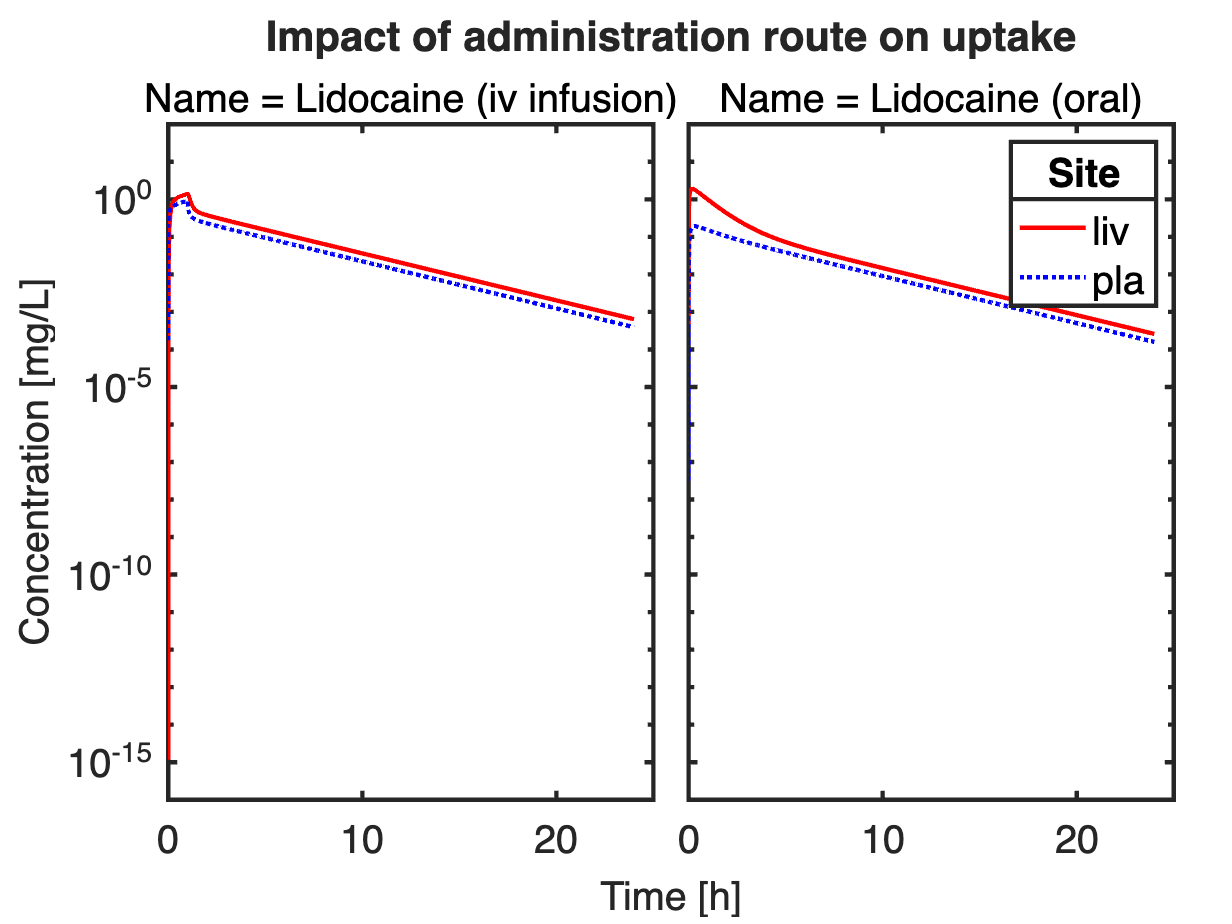

plot(indv,...
    'Site',      {'pla','liv'}, ...
    'subplot_by','Name', ...
    'group_by',  'Site',...
    'tunit',     'h',...
    'yunit',     'mg/L',...
    'yscalelog', true, ...
    'title',     'Impact of administration route on uptake',...
    'ylabel',    'Concentration')

## Working with units

2e-15*u.L*u.NA*u.nM

ans = 1.2044